`2.  N=33,` ` , 用四种窗函数设计线性相位低通滤波器，绘制相应的幅频特性曲线，观察3dB带宽和20dB 带宽以及阻带最小衰减，比较四种窗函数对滤波器特性的影响`

`Hanning窗；Hamming窗；Blackmen窗；Kaiser窗`

N = 33; M = N-1;  % 确定滤波器阶数
wc = pi/4; %  确定截止频率

`Hanning窗设计线性相位低通滤波器`

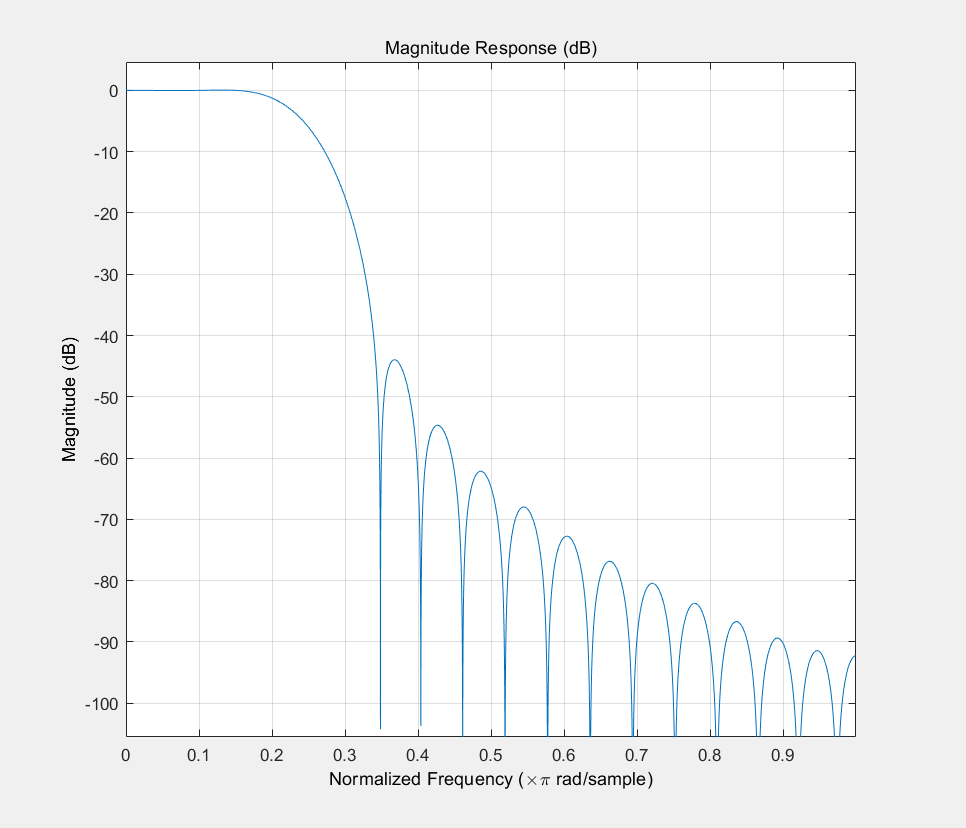

hhan = fir1(M ,wc/pi, 'low',hanning(N));
hfig = fvtool(hhan); 

`Hamming窗设计线性相位低通滤波器`

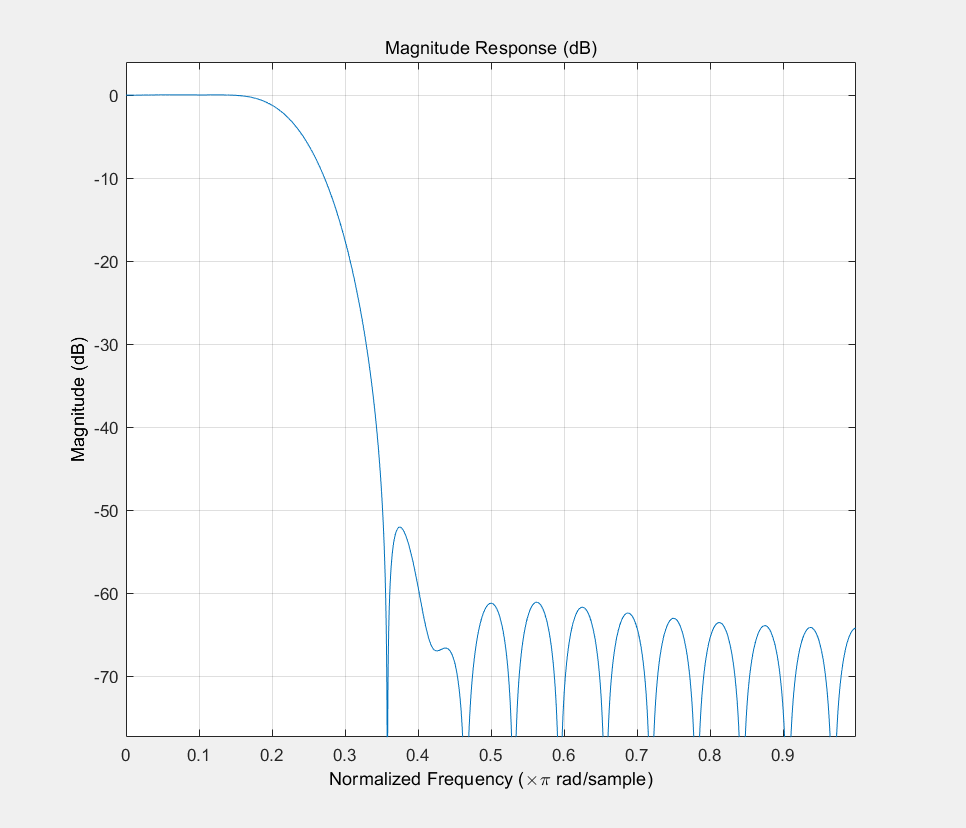

hham = fir1(M ,wc/pi, 'low');
fvtool(hham); 

`Blackmen窗设计线性相位低通滤波器`

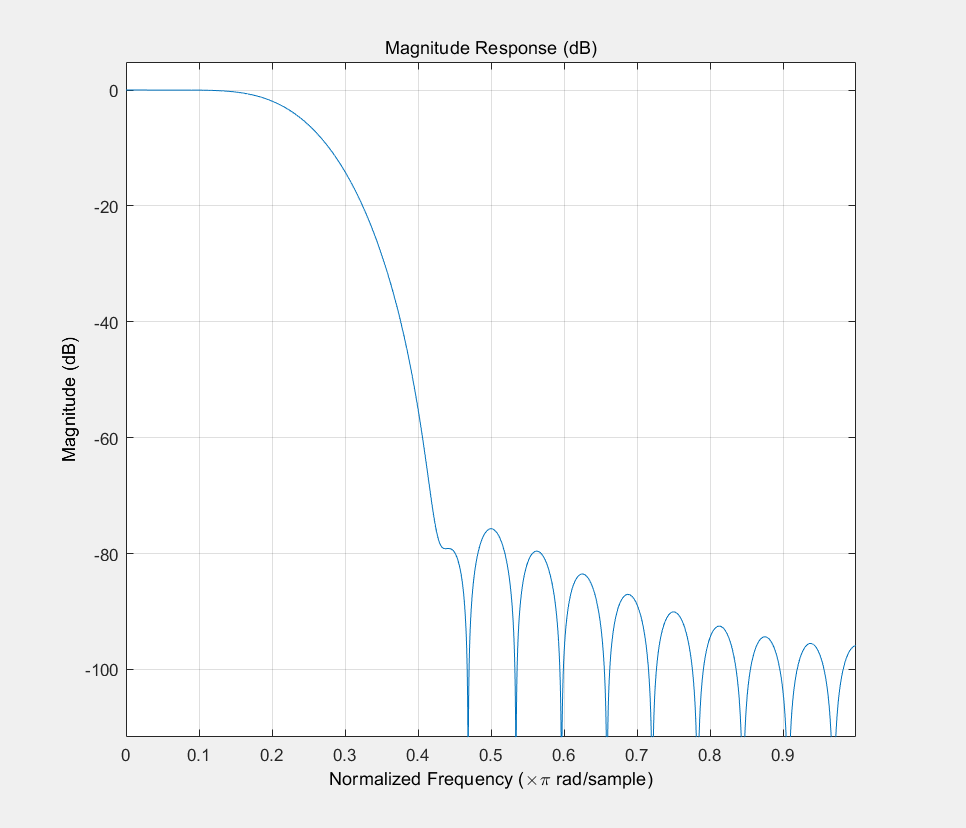

hblcm = fir1(M ,wc/pi, 'low',blackman(N));
fvtool(hblcm);

`Kaiser窗设计线性相位低通滤波器`

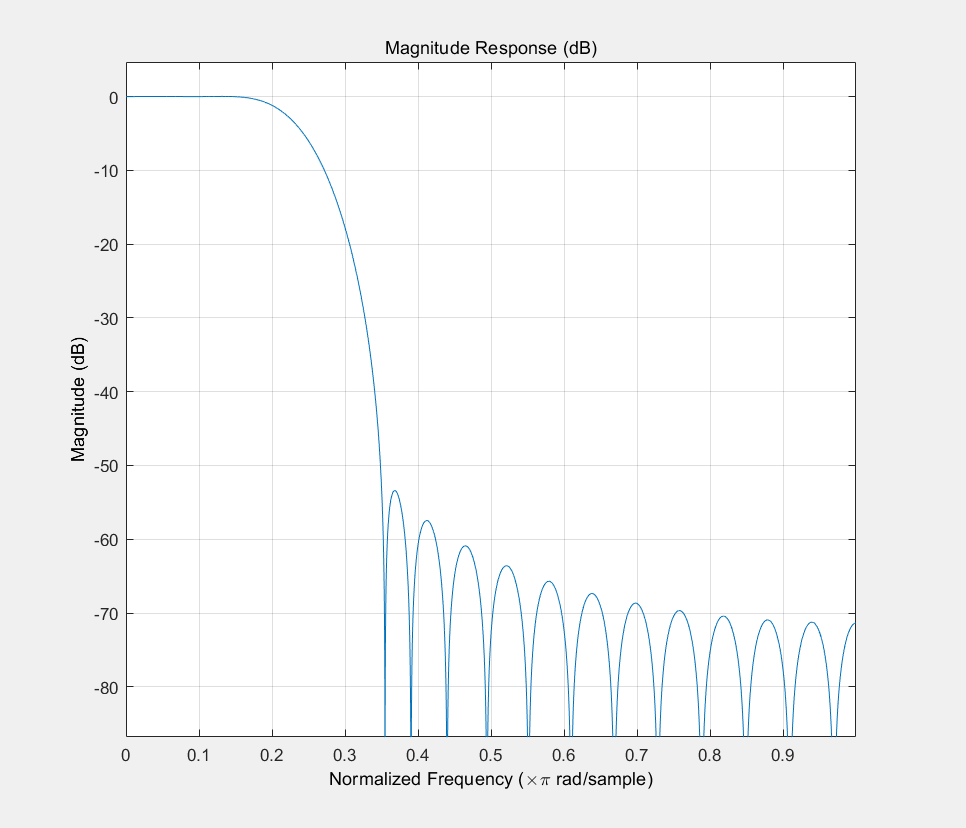

hks = fir1(M ,wc/pi, 'low',kaiser(N, 5));   % alpha = 0
fvtool(hks);

话再一起:

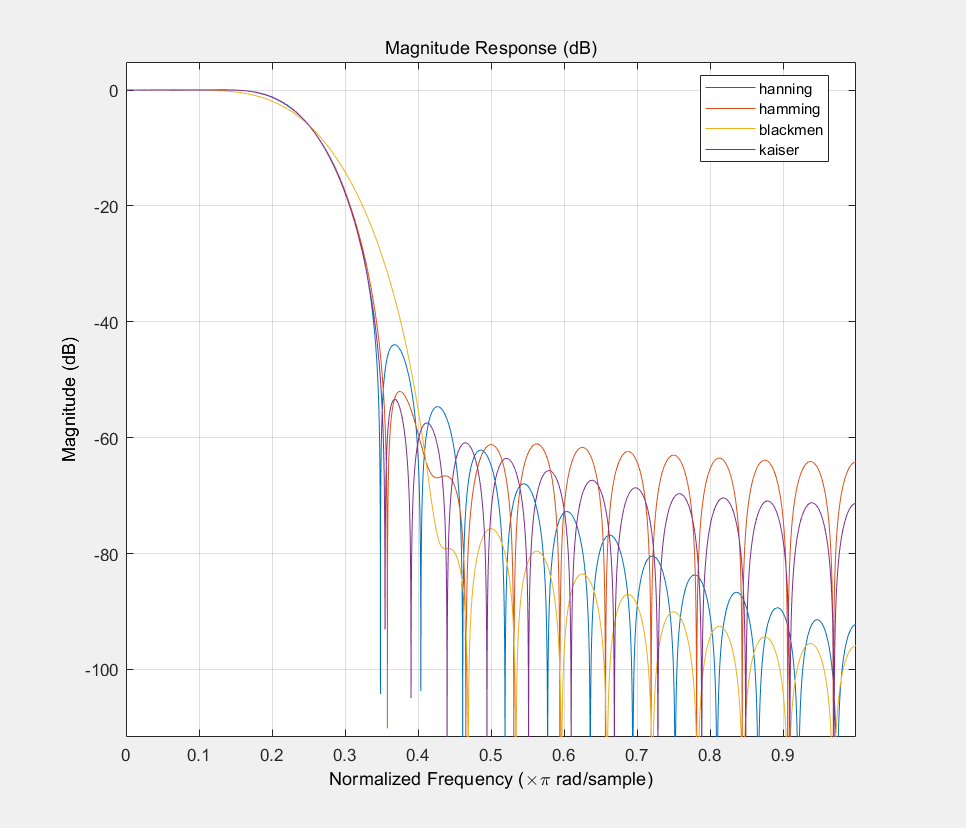

addfilter(hfig, hham);
addfilter(hfig, hblcm);
addfilter(hfig, hks);
legend(hfig, 'hanning', 'hamming', 'blackmen', 'kaiser');